# Figure 1E, 1F, 1G, S1E left

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'F028_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 10×5 cell array
    {'siCtrl DMSO'   }    {[1 2 3 4]}    {[  2 3]}    {[1]}    {[0 0 0]}
    {'siCtrl 2i 5'   }    {[1 2 3 4]}    {[  4 5]}    {[1]}    {[0 0 0]}
    {'siCtrl 2i 1'   }    {[1 2 3 4]}    {[  6 7]}    {[1]}    {[0 0 0]}
    {'siCtrl 2i 0.5' }    {[1 2 3 4]}    {[  8 9]}    {[1]}    {[0 0 0]}
    {'siCtrl Cdc7i'  }    {[1 2 3 4]}    {[10 11]}    {[1]}    {[0 0 0]}
    {'siFBXO5 DMSO'  }    {[5 6 7 8]}    {[  2 3]}    {[1]}    {[0 0 0]}
    {'siFBXO5 2i 5'  }    {[5 6 7 8]}    {[  4 5]}    {[1]}    {[0 0 0]}
    {'siFBXO5 2i 1'  }    {[5 6 7 8]}    {[  6 7]}    {[1]}    {[0 0 0]}
    {'siFBXO5 2i 0.5'}    {[5 6 7 8]}    {[  8 9]}    {[1]}    {[0 0 0]}
    {'siFBXO5 Cdc7i' }    {[5 6 7 8]}    {[10 11]}    {[1]}    {[0 0 0]}


framesPerHr = 60/12;

timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
   

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;


end

Proportion of cells in S

conds=[1 6];
timeGate = [0 20];
cols =  [0 0 .5;.4 .7 0;.941 .447 .282;.333 .302 .541; 1 .831 0;  .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];;

figure('unit','inches','position',[0 0 4 8])
nexttile
hold on
POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).goodCdk & S(conds(i)).apcExpressGate ;
    if conds(i) >= 6
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end


     mat = NaN * ones(size(data.area));
    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

     y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 

    plot(x,f,'Color',cols(i,:),'linewidth',2);
 
    sum(inds)
end

ans = 3957

ans = 1313



axis square
set(gca,'linewidth',2,'fontsize',16)
legend('Control','siEmi1','Box','off','Location','southeast','FontSize',16);
xlim([0 20]); 
xticks(0:5:20)
ylim([0 1]);
xlabel('Time since mitosis (h)','FontSize',16)
ylabel('Probability of entering S phase','FontSize',16)
hold on

APC inactivation post mitosis


nexttile

hold on
POI_align = 1;
POI_cal = 2;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
         S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).goodCdk & S(conds(i)).apcExpressGate;
    if conds(i) >= 6
        inds = inds & S(conds(i)).apcGate;
    else
        inds = inds & S(conds(i)).apcGateAll;
    end

  sum(inds)
  event = data.POI(:,POI_cal);
    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

    
    y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end

    if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
    end 

    plot(x,f,'Color',cols(i,:),'linewidth',2);
 
  
end

ans = 3957

ans = 1313

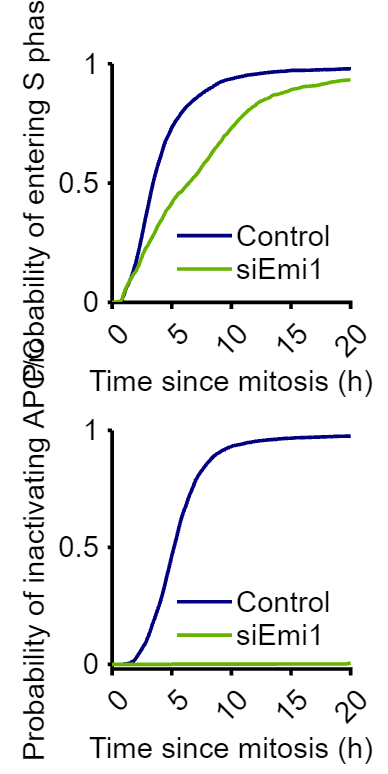



axis square
set(gca,'linewidth',2,'fontsize',16)
legend('Control','siEmi1','Box','off','Location','southeast','FontSize',16);
xlim([0 20]); 
xticks(0:5:20)
ylim([-.02 1]);
xlabel('Time since mitosis (h)','FontSize',16)
ylabel('Probability of inactivating APC/C','FontSize',16)

% print_pdf(['fig_1F_1G.pdf'])

U2OS S-APC

conds=[1];
timeGate = [0 6];
colors =  [0 0 .99;.4 .7 0;.941 .447 .282;.333 .302 .541; 1 .831 0;  .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];;

POI_align = 3;
ally = [];
groups = [];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
        data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) ;%&...
         yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,2));
    yvals = yvals(yvals < 100 & yvals > -100);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    length(yvals)
end

ans = 1051

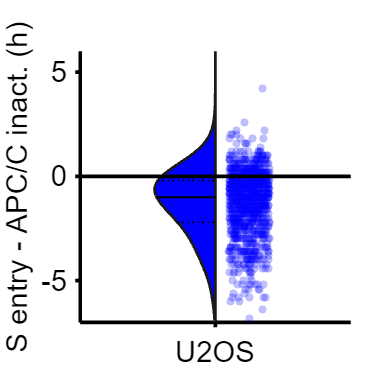

cols = repmat({colors(1,:)}',1,1);
groupcol = repmat([colors([1],:)],1,1);
figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);
ylabel(['S entry - APC/C inact. (h)'])
hline(0,'k')

 xticklabels({'U2OS'})
 ylim([-7 6])

axis square

% print_pdf(['u2os_distribution.pdf'])